%--------------------------
clear all;
cd('C:\Users\xy123\Matlab\Nlab_matlab/exp3_analysis/');

%-----------------------------------
% Acitivate at exp3_analysis
resultpath = "./results/";
ana_result = "analysis/";
Datapath = "./data/";

MatNames = {'cu0025', 'cu0129', 'pla0075', 'pla0225'};
MatNames1 = {'cu_0.025', 'cu_0.129', 'pla_0.075', 'pla_0.225'};
MatNames2 = {'cu-0.025', 'cu-0.129', 'pla-0.075', 'pla-0.225'};
HDRNames3 = [1,2,3,4,5,6,7,8,9,10,11,12,13,14,15,16,17,18,19,20,21,22,23,24,25,26,27,28,29,30];
HDRlNames2 = [19, 39, 78, 80, 102, 125, 152, 203, 226, 227, 230, 232, 243, 278, 281];
HDRNames = [5,19,34,39,42,43,78,80,102,105,125,152,164,183,198,201,202,203,209,222,226,227,230,232,243,259,272,278,281,282];
ShapeNames = {'sphere','bunny','dragon','boardA','boardB','boardC'};

% load data
load(strcat(Datapath,'Exp1_data.mat'));
load(strcat(Datapath,'Exp2_data.mat'));
load(strcat(Datapath,'Exp3_data.mat'));
load(strcat(Datapath,'Inoue_data.mat'));

%変数
Exp3RowHMSPT = Exp3RowHMSPT;
Exp3HMS = Exp3ZsHMS;
Exp3HS = Exp3ZsHS;
Exp3HM = Exp3ZsHM;
Exp3H = Exp3ZsH;
Exp3HM15 = Exp3Zs15bnyHM;
Exp3H15 = Exp3Zs15bnyH;
err_Exp3HMS = error_Exp3ZsHMS;
err_Exp3HM = error_Exp3ZsHM;
err_Exp3HS = error_Exp3ZsHS;
err_Exp3H = error_Exp3ZsH;
err_Exp3HM15 = error_Exp3HM15;
err_Exp3H15 = error_Exp3H15;

InoueHMS = InoueNormHMS;
InoueHM = InoueNormHM;
InoueHS = InoueNormHS;
InoueH = InoueNormH;
InoueHM15 = InoueNormHM15;
InoueH15 = InoueNormH15;

Exp2HM15 = Exp2ZsHM15;
Exp2H15 = Exp2ZsH15;
err_Exp2HM15 = error_Exp2ZsHM15;
err_Exp2H15 = error_Exp2ZsH15;
Exp1HM15 = Exp2ZsHM15;
Exp1H15 = Exp2ZsH15;
err_Exp1HM15 = error_Exp1ZsHM15;
err_Exp1H15 = error_Exp1ZsH15;


%---------------------------------------
% Exp3 光沢感応答
%---------------------------------------
Exp3RowHMSPT_per = permute(Exp3RowHMSPT,[2,3,1,4,5]);
Exp3RowHMSPT_reshape = reshape(Exp3RowHMSPT_per,size(Exp3RowHMSPT_per,1),size(Exp3RowHMSPT_per,2),[]);

%histgram
for mat = 1:size(Exp3HMS,2)
    figure('Position',[50,50,1300,840]);
    tiledlayout(2,3,'TileSpacing', 'compact', 'Padding', 'compact');
    for shape = 1:size(Exp3HMS,3)
        nexttile;
        values = Exp3RowHMSPT_reshape(mat,shape,:);

        histogram(values,'BinEdges',0:0.025:1);
        xlabel('Bin','FontSize',14); 
        ylabel('Frequency','FontSize',14);
        title(sprintf('%s',string(ShapeNames(shape))),'FontSize',19);
        grid on;
    end
    plotname = sprintf('%s/Exp3_bin_%s_Hist.jpg',ana_result,string(MatNames2(mat)));
    saveas(gcf, plotname);
end

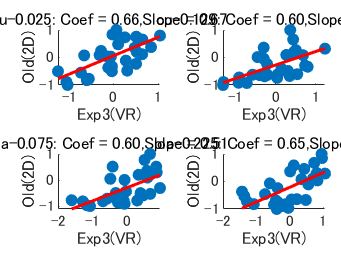

%-----------------------------------
% Exp3 vs Old HDR,Material coef
%-----------------------------------
coef_list = [];
slop_list = [];

figure;
tiledlayout(2,2,'TileSpacing', 'compact', 'Padding', 'compact');
for mat = 1:size(Exp3HM,2)
    nexttile;
    x = Exp3HM(:,mat);
    y = InoueHM(:,mat);
    r = corrcoef(x,y);
    r_value = r(1,2);
    coef_list(end+1) = r_value;
    p = polyfit(x,y,1);
    p_fit = polyval(p,x);
    slop_list(end+1) = p(1);

    scatter(x,y,'filled');
    hold on;
    plot(x,p_fit,'r-','LineWidth',1.5);
    hold off;

    xlabel('Exp3(VR)');
    ylabel('Old(2D)');
    title(sprintf('%s: Coef = %.2f,Slope = %.2f', string(MatNames2(mat)),coef_list(mat),slop_list(mat)));
end
plotname = strcat(ana_result, '/Exp3vsOld_Mat_Coef.jpg');
saveas(gcf, plotname);

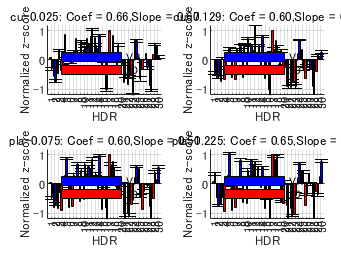


%histgram
figure;
tiledlayout(2,2,'TileSpacing', 'compact', 'Padding', 'compact');
for mat = 1:size(Exp3HM,2)
    nexttile;
    bar1 = Exp3HM(:,mat);
    err1 = err_Exp3HM(:,mat);
    bar2 = InoueHM(:,mat);
    bar_width = 0.35;
    x = 1:length(HDRNames);

    hold on;
    bar_exp3 = bar(x + bar_width/2, bar1, bar_width, 'FaceColor', 'b', 'DisplayName', '3D'); 
    errorbar(x + bar_width/2, bar1, err1, 'k', 'linestyle', 'none');
    bar_old = bar(x - bar_width/2, bar2, bar_width, 'FaceColor', 'r', 'DisplayName', '3D'); 
    %errorbar(x - bar_width/2, InoueHSNorm, error_Exp3HSNorm, 'k', 'linestyle', 'none');
    hold off;

    ylim([-1.2 1.2]);
    set(gca, 'XTick', x);
    xticklabels(HDRNames3);
    xtickangle(90);
    set(gca,'FontSize',6)

    xlabel('HDR'); 
    ylabel('Normalized z-score');
    title(sprintf('%s: Coef = %.2f,Slope = %.2f', string(MatNames2(mat)),coef_list(mat),slop_list(mat)));
    legend([bar_exp3, bar_old], {'VR', '2D'}, 'Location', 'southeast','Orientation','vertical');
    legend('boxoff');
    grid on;
end
plotname = strcat(ana_result, '/Exp3vsOld_Mat_Hist.jpg');
saveas(gcf, plotname);

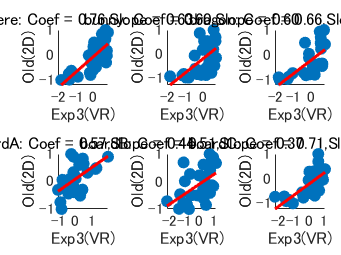

%-----------------------------------
% Exp3 vs Old HDR,Shape 
%-----------------------------------
coef_list = [];
slop_list = [];

figure;
tiledlayout(2,3,'TileSpacing', 'compact', 'Padding', 'compact');
for shape = 1:size(Exp3HS,2)
    nexttile;
    x = Exp3HS(:,shape);
    y = InoueHS(:,shape);
    r = corrcoef(x,y);
    r_value = r(1,2);
    coef_list(end+1) = r_value;
    p = polyfit(x,y,1);
    p_fit = polyval(p,x);
    slop_list(end+1) = p(1);

    scatter(x,y,'filled');
    hold on;
    plot(x,p_fit,'r-','LineWidth',1.5);
    hold off;

    xlabel('Exp3(VR)');
    ylabel('Old(2D)');
    title(sprintf('%s: Coef = %.2f,Slope = %.2f', string(ShapeNames(shape)),coef_list(shape),slop_list(shape)));
end
plotname = strcat(ana_result, '/Exp3vsOld_Shape_Coef.jpg');
saveas(gcf, plotname);

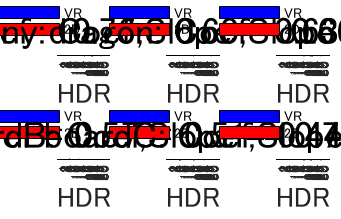


figure('Position',[50,50,1300,840]);
tiledlayout(2,3,'TileSpacing', 'compact', 'Padding', 'compact');
for shape = 1:size(Exp3HS,2)
    nexttile;
    bar1 = Exp3HS(:,shape);
    err1 = err_Exp3HS(:,shape);
    bar2 = InoueHS(:,shape);
    bar_width = 0.35;
    x = 1:length(HDRNames);

    hold on;
    bar_exp3 = bar(x + bar_width/2, bar1, bar_width, 'FaceColor', 'b', 'DisplayName', '3D'); 
    errorbar(x + bar_width/2, bar1, err1, 'k', 'linestyle', 'none');
    bar_old = bar(x - bar_width/2, bar2, bar_width, 'FaceColor', 'r', 'DisplayName', '3D'); 
    %errorbar(x - bar_width/2, InoueHSNorm, error_Exp3HSNorm, 'k', 'linestyle', 'none');
    hold off;

    ylim([-1.2 1.2]);
    set(gca, 'XTick', x);
    xticklabels(HDRNames3);
    xtickangle(90);
    set(gca,'FontSize',8)

    xlabel('HDR','FontSize',14); 
    ylabel('Normalized z-score','FontSize',14);
    title(sprintf('%s: Coef = %.2f,Slope = %.2f', string(ShapeNames(shape)),coef_list(shape),slop_list(shape)),'FontSize',19);
    legend([bar_exp3, bar_old], {'VR', '2D'}, 'Location', 'southeast','Orientation','vertical');
    legend('boxoff');
    grid on;
end
plotname = strcat(ana_result, '/Exp3vsOld_Shape_Hist.jpg');
saveas(gcf, plotname);

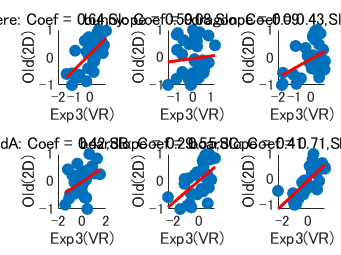

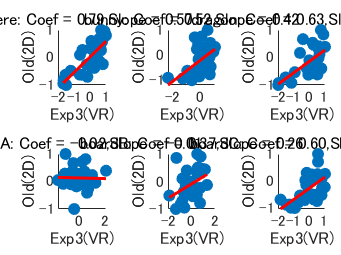

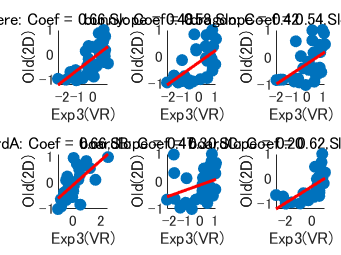

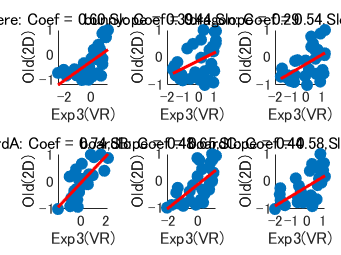

%-----------------------------------
% Exp3 vs Old HDR,Material,Shape coef
%-----------------------------------
coef_list = zeros(size(Exp3HMS,2),size(Exp3HMS,3));
slop_list = zeros(size(Exp3HMS,2),size(Exp3HMS,3));

for mat = 1:size(Exp3HMS,2)
    figure;
    tiledlayout(2,3,'TileSpacing', 'compact', 'Padding', 'compact');
    for shape = 1:size(Exp3HMS,3)
        nexttile;
        x = Exp3HMS(:,mat,shape);
        y = InoueHMS(:,mat,shape);
        r = corrcoef(x,y);
        r_value = r(1,2);
        coef_list(mat,shape) = r_value;
        p = polyfit(x,y,1);
        p_fit = polyval(p,x);
        slop_list(mat,shape) = p(1);
    
        scatter(x,y,'filled');
        hold on;
        plot(x,p_fit,'r-','LineWidth',1.5);
        hold off;
    
        xlabel('Exp3(VR)');
        ylabel('Old(2D)');
        title(sprintf('%s: Coef = %.2f,Slope = %.2f',string(ShapeNames(shape)),coef_list(mat,shape),slop_list(mat,shape)));
    end
    plotname = sprintf('%s/Exp3vsOld_MS_%s_Coef.jpg',ana_result,string(MatNames2(mat)));
    saveas(gcf, plotname);
end

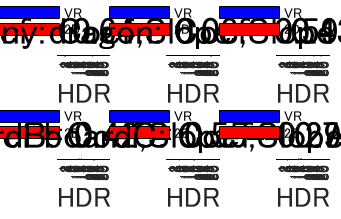

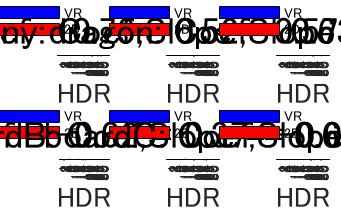

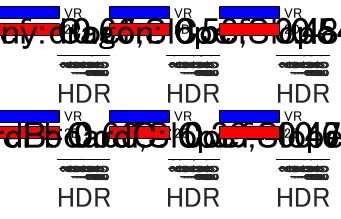

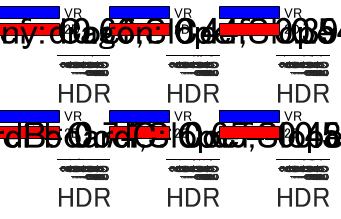


%histgram
for mat = 1:size(Exp3HMS,2)
    figure('Position',[50,50,1300,840]);
    tiledlayout(2,3,'TileSpacing', 'compact', 'Padding', 'compact');
    for shape = 1:size(Exp3HMS,3)
        nexttile;
        bar1 = Exp3HMS(:,mat,shape);
        err1 = err_Exp3HMS(:,mat,shape);
        bar2 = InoueHMS(:,mat,shape);
        bar_width = 0.35;
        x = 1:length(HDRNames);
    
        hold on;
        bar_exp3 = bar(x + bar_width/2, bar1, bar_width, 'FaceColor', 'b', 'DisplayName', '3D'); 
        errorbar(x + bar_width/2, bar1, err1, 'k', 'linestyle', 'none');
        bar_old = bar(x - bar_width/2, bar2, bar_width, 'FaceColor', 'r', 'DisplayName', '3D'); 
        %errorbar(x - bar_width/2, InoueHSNorm, error_Exp3HSNorm, 'k', 'linestyle', 'none');
        hold off;
    
        ylim([-1.2 1.2]);
        set(gca, 'XTick', x);
        xticklabels(HDRNames3);
        xtickangle(90);
        set(gca,'FontSize',8)
    
        xlabel('HDR','FontSize',14); 
        ylabel('Normalized z-score','FontSize',14);
        title(sprintf('%s: Coef = %.2f,Slope = %.2f',string(ShapeNames(shape)),coef_list(mat,shape),slop_list(mat,shape)),'FontSize',19);
        legend([bar_exp3, bar_old], {'VR', '2D'}, 'Location', 'southeast','Orientation','vertical');
        legend('boxoff');
        grid on;
    end
    plotname = sprintf('%s/Exp3vsOld_MS_%s_Hist.jpg',ana_result,string(MatNames2(mat)));
    saveas(gcf, plotname);
end

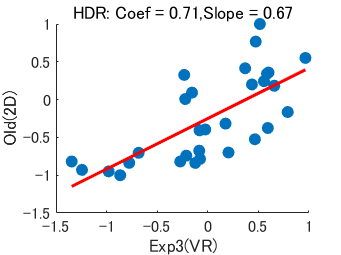

%-----------------------------------
% Exp3 vs Old HDR coef
%-----------------------------------
figure;

x = Exp3H(:);
y = InoueH(:);
r = corrcoef(x,y);
r_value = r(1,2);
p = polyfit(x,y,1);
p_fit = polyval(p,x);

scatter(x,y,'filled');
hold on;
plot(x,p_fit,'r-','LineWidth',1.5);
hold off;

xlabel('Exp3(VR)');
ylabel('Old(2D)');
title(sprintf('HDR: Coef = %.2f,Slope = %.2f', r_value,p(1)));

plotname = strcat(ana_result, '/Exp3vsOld_HDR_Coef.jpg');
saveas(gcf, plotname);
hold off;

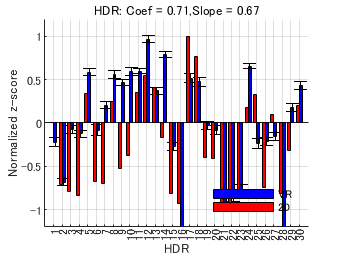


%histgram
bar1 = Exp3H(:);
err1 = err_Exp3H(:);
bar2 = InoueH(:);

figure;
bar_width = 0.35;
x = 1:length(HDRNames);

hold on;
bar_exp3 = bar(x + bar_width/2, bar1, bar_width, 'FaceColor', 'b', 'DisplayName', '3D'); 
errorbar(x + bar_width/2, bar1, err1, 'k', 'linestyle', 'none');
bar_old = bar(x - bar_width/2, bar2, bar_width, 'FaceColor', 'r', 'DisplayName', '3D'); 
%errorbar(x - bar_width/2, InoueHSNorm, error_Exp3HSNorm, 'k', 'linestyle', 'none');
hold off;

ylim([-1.2 1.2]);
set(gca, 'XTick', x);
xticklabels(HDRNames3);
xtickangle(90);
set(gca,'FontSize',6)

xlabel('HDR'); 
ylabel('Normalized z-score');
title(sprintf('HDR: Coef = %.2f,Slope = %.2f', r_value,p(1)));
legend([bar_exp3, bar_old], {'VR', '2D'}, 'Location', 'southeast','Orientation','vertical');
legend('boxoff');
grid on;
plotname = strcat(ana_result, '/Exp3vsOld_HDR_Hist.jpg');
saveas(gcf, plotname);

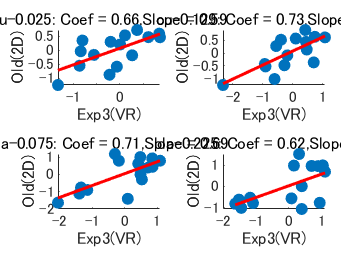

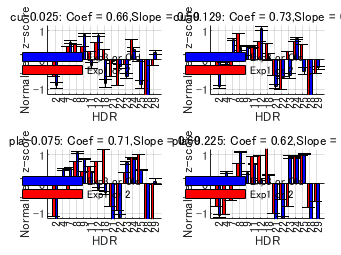

%-----------------------------------
% exp1,exp2 VS VR HDR,material
%-----------------------------------
title = 'Exp2vsExp3_HM';
Make_2dims_vsgraph_Coef_Hist(Exp3HM15,err_Exp3HM15,Exp2HM15,err_Exp2HM15,title);

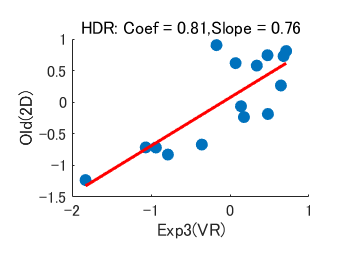

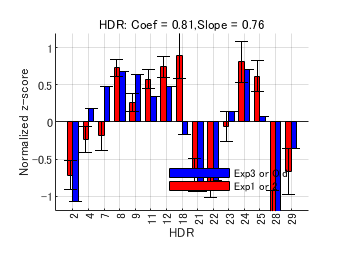

title = 'Exp2vsExp3_HDR';
Make_1dims_vsgraph_Coef_Hist(Exp3H15,err_Exp3H15,Exp2H15,err_Exp2H15,title);

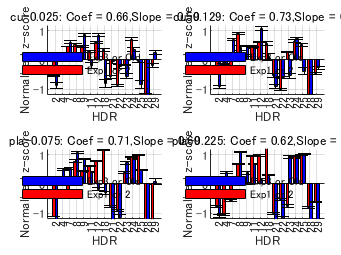

title = 'Exp1vsExp3_HM';
Make_2dims_vsgraph_Coef_Hist(Exp3HM15,err_Exp3HM15,Exp1HM15,err_Exp1HM15,title);

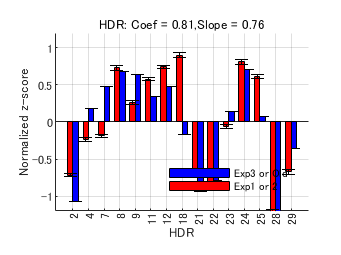

title = 'Exp1vsExp3_HDR';
Make_1dims_vsgraph_Coef_Hist(Exp3H15,err_Exp3H15,Exp1H15,err_Exp1H15,title);

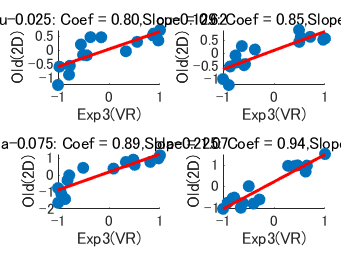

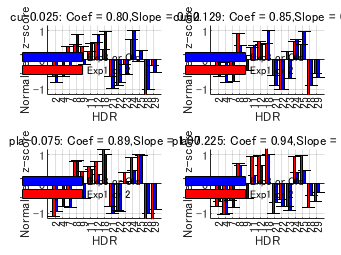

%-----------------------------------
% exp1,exp2 VS Old HDR,material
%-----------------------------------
errorinoue1 = zeros(size(InoueHM15));
errorinoue2 = zeros(size(InoueH15));

title = 'Exp2vsOld_HM';
Make_2dims_vsgraph_Coef_Hist(InoueHM15,errorinoue1,Exp2HM15,err_Exp2HM15,title);

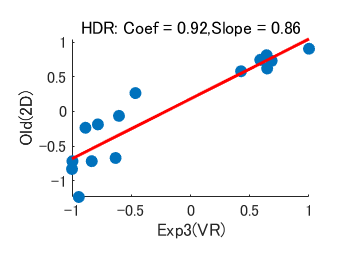

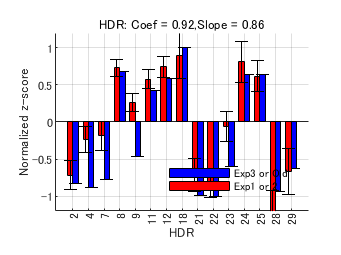

title = 'Exp2vsOld_HDR';
Make_1dims_vsgraph_Coef_Hist(InoueH15,errorinoue2,Exp2H15,err_Exp2H15,title);

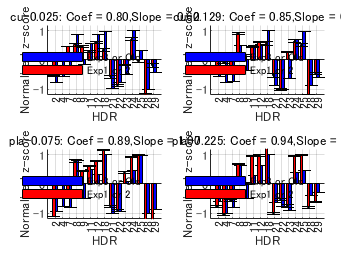

title = 'Exp1vsOld_HM';
Make_2dims_vsgraph_Coef_Hist(InoueHM15,errorinoue1,Exp1HM15,err_Exp1HM15,title);

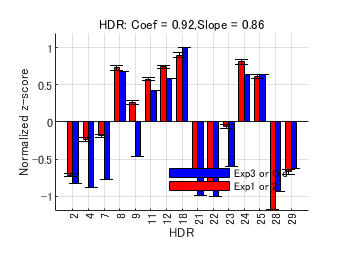

title = 'Exp1vsOld_HDR';
Make_1dims_vsgraph_Coef_Hist(InoueH15,errorinoue2,Exp1H15,err_Exp1H15,title);

%{
%-----------------------------------
% Exp3 Material Shape
%-----------------------------------
for mat = 1:size(Exp3HMS,2)
    figure;
    hold on;
    for shape = 1:size(Exp3HMS,3)
        subplot(2, 3, shape);
        bar_width = 0.35;
        x = 1:length(HDRNames);
    
        bar(x + bar_width/2, Exp3HMS(:,mat, shape), bar_width, 'FaceColor', 'b', 'DisplayName', '3D'); 
        errorbar(x + bar_width/2, Exp3HMS(:,mat,shape), err_Exp3HMS(:,mat,shape), 'k', 'linestyle', 'none');
    
        ylim([-1.2 1.2]);
        set(gca, 'XTick', 1:length(HDRNames3));
        set(gca, 'XTickLabel', HDRNames3, 'FontSize', 14);
        xlabel('HDR', 'FontSize', 16); 
        ylabel('Average z-score', 'FontSize', 16);
        title(['compare of ' MatNames2{mat} '&' ShapeNames{shape}], 'FontSize', 16);
        %legend([b2,b3],{'2D','3D'}, 'Location', 'best');
    end
    plotname = strcat(ana_result, '/Exp3_MS_', MatNames2{mat},'.jpg');
    saveas(gcf, plotname);
    hold off;
end

%-----------------------------------
% Exp3 Material
%-----------------------------------
figure;
hold on;
for mat = 1:4
    subplot(2, 2, mat);
    bar_width = 0.35;
    x = 1:length(HDRNames);

    bar(x + bar_width/2, Exp3HM(:,mat), bar_width, 'FaceColor', 'b', 'DisplayName', '3D'); 
    errorbar(x + bar_width/2, Exp3HM(:,mat), error_Exp3HMSNorm(:,mat), 'k', 'linestyle', 'none');

    ylim([-1.2 1.2]);
    set(gca, 'XTick', 1:length(HDRNames3));
    set(gca, 'XTickLabel', HDRNames3, 'FontSize', 14);
    xlabel('HDR', 'FontSize', 16); 
    ylabel('Average z-score', 'FontSize', 16);
    title(['compare of ' MatNames2{row}], 'FontSize', 16);
    %legend([b2,b3],{'2D','3D'}, 'Location', 'best');
end
plotname = strcat(ana_result, '/Exp3_Material', '.jpg');
saveas(gcf, plotname);
hold off;

%-----------------------------------
% Exp3 Shape
%-----------------------------------
figure;
hold on;
for shape = 1:size(Exp3HS,2)
    subplot(2,3,shape);
    bar_width = 0.35;
    x = 1:length(HDRNames);

    bar(x + bar_width/2, Exp3HS(shape, :), bar_width, 'FaceColor', 'b', 'DisplayName', '3D'); 
    errorbar(x + bar_width/2, Exp3HS(shape, :), error_Exp3HSNorm(shape,:), 'k', 'linestyle', 'none');

    ylim([-1.2 1.2]);
    set(gca, 'XTick', 1:length(HDRNames3));
    set(gca, 'XTickLabel', HDRNames3, 'FontSize', 14);
    xlabel('HDR', 'FontSize', 16); 
    ylabel('Average z-score', 'FontSize', 16);
    title(['compare of ' ShapeNames{shape}], 'FontSize', 16);
    %legend([b2,b3],{'2D','3D'}, 'Location', 'best');

end
plotname = strcat(ana_result, '/Exp3_', 'Shape','.jpg');
saveas(gcf, plotname);
hold off;

%-----------------------------------
% Exp3 HDR
%-----------------------------------
figure;
hold on;
bar_width = 0.35;
x = 1:length(HDRNames);
avb = bar(x + bar_width/2, Exp3H, bar_width, 'FaceColor', 'b', 'DisplayName', '3D'); 
avh = errorbar(x + bar_width/2, Exp3H, error_Exp3HNorm, 'k', 'linestyle', 'none');
ylim([-1.2 1.2]);
set(gca, 'XTick', 1:length(HDRNames3));
set(gca, 'XTickLabel', HDRNames3, 'FontSize', 14);
xlabel('HDR', 'FontSize', 16); 
ylabel('Normalized z-score', 'FontSize', 16);
title('HDR', 'FontSize', 16);
plotname = strcat(ana_result, '/Exp3_HDR.jpg');
saveas(gcf, plotname);
hold off;

%-----------------------------------
% Inoue material
%-----------------------------------
figure;
hold on;
for mat = 1:size(InoueHM,2)
    subplot(2,2,mat);
    bar_width = 0.35;
    x = 1:length(colNames);

    b3 = bar(x + bar_width/2, InoueMHNorm(:,mat), bar_width, 'FaceColor', 'b', 'DisplayName', '3D'); 
    %h3 = errorbar(x + bar_width/2, InoueMHNorm(:,row), error_exp3(row,:), 'k', 'linestyle', 'none');

    ylim([-1.2 1.2]);
    set(gca, 'XTick', 1:length(colNames));
    set(gca, 'XTickLabel', colNames, 'FontSize', 14);
    xlabel('HDR', 'FontSize', 16); 
    ylabel('Average z-score', 'FontSize', 16);
    title(['compare of ' InoueMatname{mat}], 'FontSize', 16);
end
plotname = strcat(ana_result, '/Old_Material','.jpg');
saveas(gcf, plotname);
hold off;

%-----------------------------------
% Inoue Shape
%-----------------------------------
figure;
hold on;
for shape = 1:size(InoueHS,2)
    bar_width = 0.35;
    x = 1:length(colNames);

    b3 = bar(x + bar_width/2, InoueSHNorm(:,shape), bar_width, 'FaceColor', 'b', 'DisplayName', '3D'); 
    %h3 = errorbar(x + bar_width/2, InoueSHNorm(:,row), error_exp3(row,:), 'k', 'linestyle', 'none');

    ylim([-1.2 1.2]);
    set(gca, 'XTick', 1:length(colNames));
    set(gca, 'XTickLabel', colNames, 'FontSize', 14);
    xlabel('HDR', 'FontSize', 16); 
    ylabel('Normalized z-score', 'FontSize', 16);
    title(['compare of ' InoueShapeName{shape}], 'FontSize', 16);
end
plotname = strcat(ana_result, '/Old_Shape', '.jpg');
saveas(gcf, plotname);
hold off;

%-----------------------------------
% Inoue material shape
%-----------------------------------
for mat = 1:size(InoueHMS,2)
    figure;
    hold on;
    for shape = 1:size(InoueHMS,3)
        subplot(2,3,shape);
        bar_width = 0.35;
        x = 1:length(HDRNames);
    
        bar(x + bar_width/2, InoueHMS(:,mat, shape), bar_width, 'FaceColor', 'b', 'DisplayName', '3D'); 
        %errorbar(x + bar_width/2, InoueMHSNorm(:,matnum, shapenum), error_Exp3MHS(matnum,:,shapenum), 'k', 'linestyle', 'none');
    
        ylim([-1.2 1.2]);
        set(gca, 'XTick', 1:length(HDRNames3));
        set(gca, 'XTickLabel', HDRNames3, 'FontSize', 14);
        xlabel('HDR', 'FontSize', 16); 
        ylabel('Average z-score', 'FontSize', 16);
        title(['compare of ' InoueMatname{mat} '&' InoueShapeName{row}], 'FontSize', 16);
        %legend([b2,b3],{'2D','3D'}, 'Location', 'best');
    end
    plotname = strcat(ana_result, '/Old_MS_', InoueMatname{mat},'.jpg');
    saveas(gcf, plotname);
    hold off;
end
%}